# Dynamics Homework 2 Question 2

# Rollercoaster

## Olivia Jo Bradley

% Problem
clc
clearvars

% initial position
x0 = 0; % m
y0 = 100; % m

% initial velocity
dx = 0;
dy = 0;

% pack initial conditions into column vector
init = [x0 dx y0 dy]';

% run simulation
[t,p] = simulation(init);

y = function_handle with value:
    @(x)h*(1-B*(x/L))*cos((3*pi*x)/(2*L))^2


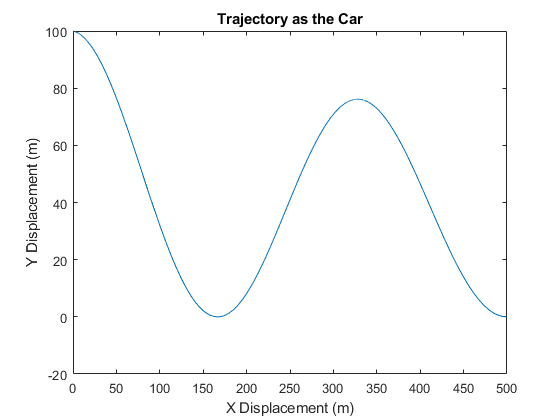


% plotting
x = p(:,1);
y = p(:,3);
figure()
plot(x,y)
title('Trajectory as the Car')
xlabel("X Displacement (m)")
ylabel("Y Displacement (m)")

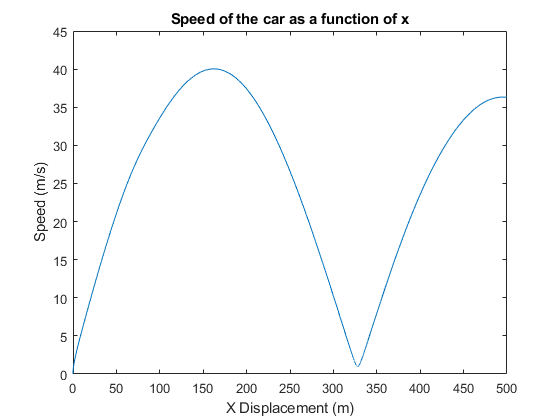


speeed = sqrt(p(:,2).^2 + p(:,4).^2);
plot(x, speeed)
title('Speed of the car as a function of x')
xlabel("X Displacement (m)")
ylabel("Speed (m/s)")


disp("The ride is " + t(end) + " seconds long")

The ride is 42.3931 seconds long


function [t,p] = simulation(init)
    
    % time span
    tspan = [0:.01:50];

    % simulation params, used in ODE funcs
    g = 9.8;
    m = 500; % kg
    A = 4.0; % m^2
    Cd = 0.1; % coeff
    rho = 1.02; % kg/m^3
    B = 0.361; % Estimated Value 
    h = 100;
    L = 500;
    
    c = rho*Cd*A/(2*m);
   
x = sym('x');
y = @(x) h*(1-B*(x/L))*cos((3*pi*x)/(2*L))^2
    
a = matlabFunction(diff(y(x)));

b = matlabFunction(diff(a(x)));
    
    % use ode45 and stop at event
    options = odeset('Events', @eventFcn, 'RelTol', 1e-6);
    [t,p] = ode45(@f,tspan,init,options);
    
    % define ODEs
    function dpdt = f(~,p)
Q = [1 0 0 0 0;
     0 1 0 0 0;
     0 0 1 0 a(p(1))/(m*sqrt(1+a(p(1))^2));
     0 0 0 1 -1/(m*sqrt(1+a(p(1))^2));
     0 0 a(p(1)) -1 0];

V = norm([p(2) p(4)]);
V = P(:,2).^2 + P(:,4).^2;


r = [p(2), p(4), -c*V^2/(sqrt(1+a(p(1)))), -c*a(p(1))*V^2/(sqrt(1+a(p(1))))-g, -b(p(1))*p(2)^2]';
    
z = (Q\r)';

        dx = z(1);  % x velocity
        ddx = z(3);    % x accel
        dy = z(2);  % y velocity
        ddy = z(4);    % y accel
        
        % pack ODEs into column vector
        dpdt = [dx ddx dy ddy]';
    end
    
    function [position,isterminal,direction] = eventFcn(~,p)
        position = p(1)-L; % The value that we want to be zero
        isterminal = 1;  % Halt integration 
        direction = 0;   % The zero can be approached from either direction
    end

end